# Laboratorio 2 Robótica: Modelo Geométrico Inverso

## Universidad Nacional de Colombia

## Alejandro Ojeda Olarte, Brayan Calderon, Mateo Rodriguez

## Modelo Geométrico Inverso

Teniendo en cuenta el robot asignado y los resultados obtenidos en el Lab 1  Análisis de las características de un Robot Industrial y Modelo geométrico directo. Resuelva los siguientes enunciados.

#### 1.Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. Haga una  descripción detallada  del  proceso  haciendo  uso  de  imágenes  y  dibujos  que  ayuden  visualizar  de dónde provienen las ecuaciones encontradas.

Primero se realiza el diagrama de lo que son puntos de referencia de robot.

####            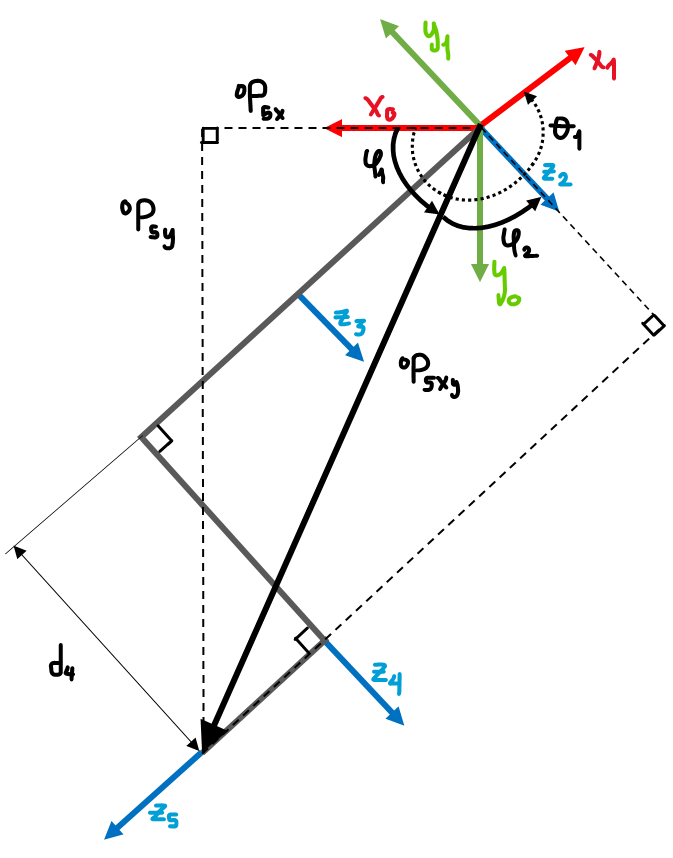

Con este primero vamos a tener en cuenta que, el robot posee varios ejes de rotación paralelos, y no posee muñeca esférica, de manera que no podemos solucionarlo por el método de desacople estudiado anteriormente en clase.

La articulación 6 dado que rota únicamente en un eje, puede evitarse buscando despejar la rotación de la articulación 1, con el siguiente despeje.


$$^{0}P_5=  \,^{0}T_6  \left[\matrix{ 0 \cr 0 \cr -d6  \cr 1 }   \right]$$


Apoyados en la gráfica de la siguiente imagen podemos observar que:

###            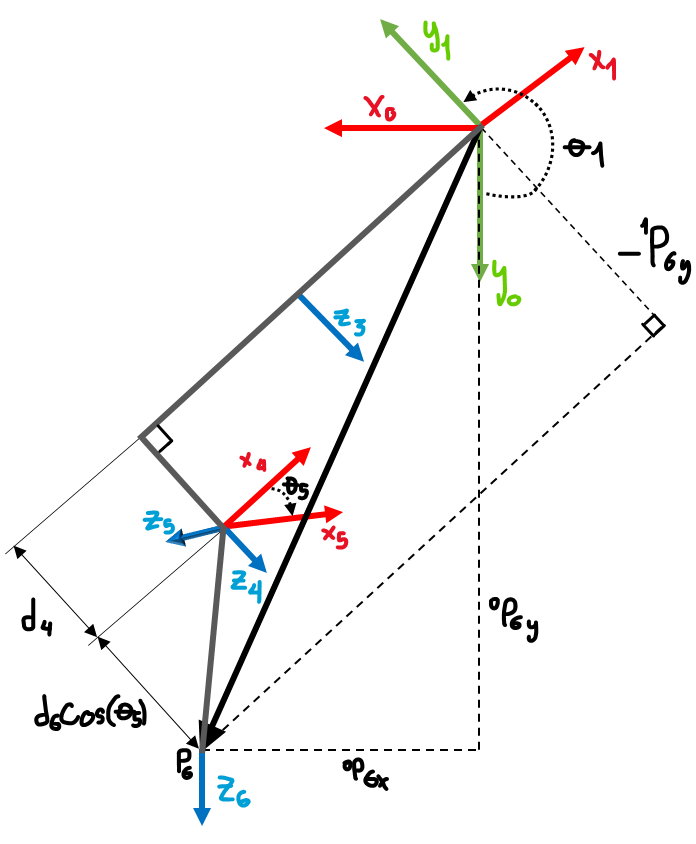


$$\theta_1= \phi_1 + \phi_2 +\frac{\pi}{2}$$


Donde de la imagen se observa que


$$\phi_1=atan2(^{0}P_{5y},^{0}P_{5x})$$


Y de forma similar se tiene que


$$\cos{\phi_2} = \frac{d4}{| ^{0}P_{5xy} | $$



$$\theta_1 = \phi_1 \pm acos( \frac{d4}{ \sqrt{^{0}P_{5x} ^2 + ^{0}P_{5y}^2}} )$$


Donde cada resultado corresponderá a la solución de hombro derecho o de hombro izquierdo.

Posteriormente, dado que se tiene la primera, se procede a solucionar la articulación 5, para lo que se grafica el robot incluyendo la sexta articulación.

Con esta imagen se busca encontrar el vector de la articulación 6 a la 1, cuyo componente en y también puede verse como una rotación del vector desde la articulación 0 a la 6 ($^{0}P_6$) en el eje $Z$ de la articulación 1.


$$- ^{1}P_{6y}=d4+d6 \cos{\theta_5}$$



$$^{0}P_6 = \, ^{0}R_1 \cdot ^{1}P_6$$



$$^{1}P_6 = \, ^{0}R_1^T \cdot ^{0}P_6 $$



$$ \left[\matrix{ ^{1}P_{6x} \cr ^{1}P_{6y} \cr ^{1}P_{6z}  }   \right]= \left[\matrix{ cos(\theta_1) & sin(\theta_1) & 0 \cr -sin(\theta_1)  & cos(\theta_1) & 0 \cr 0 & 0 & 1} \right]  \left[\matrix{ ^{0}P_{6x} \cr ^{0}P_{6y} \cr ^{0}P_{6z}  }   \right]$$



$$^{1}P_{6y}=\, ^{0}P_{6x} (-\sin{\theta_1})+\,^{0}P_{6y}\cos{\theta_1}$$


Que realizando el despeje con la ecuación que tiene el valor de la articulación 5,


$$\theta_5 = \pm acos( \frac{ ^{0}P_{6x} \sin{\theta_1} - ^{0}P_{6y} \cos{\theta_1} - d4 } {d6} )$$


Que de la misma manera tiene dos soluciones, muñeca arriba o abajo.

Para encontrar $\theta_6
$ se analiza y1 visto desde el sistema coordenado de la articulación 6. Este siempre será paralelo a z2, z3, y z4 vistos desde el mismo sistema coordenado, de manera que solo dependen de $\theta_5$ y $\theta_6$. Con este dato se puede analizar que puede describirse como coordenadas esféricas. Con este dato y la gráfica observamos que:

###             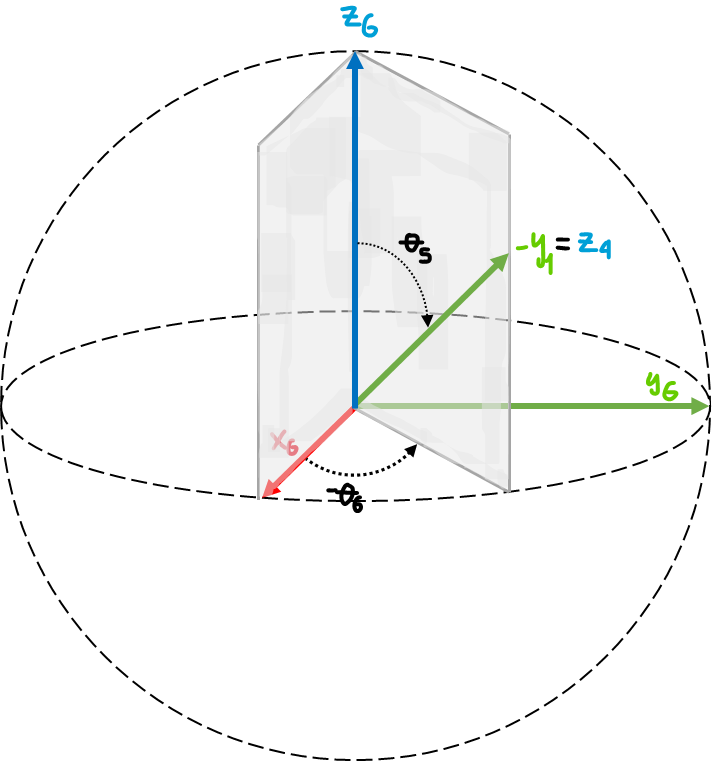


$$-^{6}\hat{Y}_1 = \left[\matrix{\sin{\theta_5} \cos{-\theta_6} \cr \sin{\theta_5} \sin{-\theta_6} \cr -\cos{\theta_5} }   \right]$$


Y analizando de manera similar como se hizo para la articulación anterior.


$$^{6}\hat{Y}_1 = \left[\matrix{ -^{6}\hat{X}_{0x} \sin{\theta_1} + ^{6}\hat{Y}_{0x} \cos{\theta_1}  \cr -^{6}\hat{X}_{0y} \sin{\theta_1} + ^{6}\hat{Y}_{0y} \cos{\theta_1}  \cr -^{6}\hat{X}_{0z} \sin{\theta_1} + ^{6}\hat{Y}_{0z} \cos{\theta_1}  }   \right]$$


Con el que se obtiene el sistema de ecuaciones siguiente


$$\cos{\theta_6} = \frac{ ^{6}\hat{X}_{0x} \sin{\theta_1} -  ^{6}\hat{Y}_{0x} \cos{\theta_1}}{  \sin{\theta_5}}$$



$$\sin{\theta_6} = \frac{- ^{6}\hat{X}_{0y} \sin{\theta_1} +  ^{6}\hat{Y}_{0y} \cos{\theta_1}}{  \sin{\theta_5}}$$


Y obtenemos el resultado


$$\theta_6=atan2( \frac{- ^{6}\hat{X}_{0y} \sin{\theta_1} +  ^{6}\hat{Y}_{0y} \cos{\theta_1}}{  \sin{\theta_5}} ,  \frac{ ^{6}\hat{X}_{0x} \sin{\theta_1} -  ^{6}\hat{Y}_{0x} \cos{\theta_1}}{  \sin{\theta_5}} )$$


Es importante notar que cuando ambos numeradores o el denominador vale 0 esta respuesta es indeterminada, que corresponde a la configuración donde las articulaciones 2,3,4 y 6 son paralelas, para estos casos se sugiere que den un $\theta_6$ para tener una solución completa del sistema.

Para las soluciones de las articulaciones 2,3 y 4, se puede observar que corresponde a un manipulador planar de 3DOF, de manera que se soluciona de esta manera. De la imagen se observa que el vector de la articulacion 1 a 4, depende únicamente de $\theta_3$, o de otra forma similar, por $\phi_3$.


$$\phi_3 = \frac{ (-a_2)^2 + (-a_3)^2 - |^{1}P_{4xz}|^2 }{  2 (-a_2)(-a_3) } = \frac{ {a_{2}} ^2 +{a_3}^2  - |^{1}P_{4xz}|^2}{ 2a_2 a_3}$$


De donde


$$\cos{\theta_3}= -\frac{ {a_{2}} ^2 +{a_3}^2  - |^{1}P_{4xz}|^2}{ 2a_2 a_3}$$



$$\theta_3= \pm acos (\frac{   |^{1}P_{4xz}|^2- {a_{2}} ^2 -{a_3}^2  }{ 2a_2 a_3})$$


Y con la misma imagen se tiene que 


$$\phi_1= atan2(-^{1}P_{4z} , -^{1}P_{4x})$$


Y por ley de senos


$$\phi_2 = asin( \frac{-a_3 \sin{\phi_3}}{ |^{1}P_{4xz}| })$$



$$\theta_2 = \phi_1 - \phi_2$$


Y finalmente dado que lo que se necesita viene de $^{3}T_4 $ se tiene que


$$\theta_4 = atan2( \sin{\theta_4} \cos{\alpha_3} , \cos{\theta_4})$$


#### 2.En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.

#### 3.Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique

- **¿Cuál es la diferencia entre estas funciones?**

Existen distintas funciones para hallar la cinematica inversa de un robot manipulador utilizando el Toolbox de Peter Corke, dichas funciones son:

-  **Ikine6s**: Halla la cinematica directa para un manipulador de 6 grados de libertad que cuente con muñeca esferica, utiliza un método analitico para su resolución

-  **Ikine**: Halla la cinematica inversa de un manipulador utilizando métodos iterativos, es más lenta que la anterior pero suele funcionar bien para cualquier manipulador

-  **Ikunc**: Halla la cinematica inversa utilizando algún método de optimización

-  **Ikonc** Halla la cinematica inversa con método de optimización pero con limites en las articulaciones

-  **Ikine_sym** Halla la cinematica inversa de manera simbolica 

- ¿Cuál debe usar para su robot y por qué? (Revise la documentación del Toolbox)

Para el robot industrial UR3 se debe utilizar la función **ikine** debido a que este no es del tipo muñeca esferica por tanto debemos realizar una solución de manera iterativa, de igual forma toca especificar una mascara para la obtención de la solución debido a que si no se define no se logra converger a una solución.

%Cinematica directa
%Creación eslabones
clear all;clc;
L(1) = Link([0 0.152 0 0],'modified');
L(2) = Link([0 0.120 0 pi/2 0 pi/2],'modified');
L(3) = Link([0 0 0.244 0],'modified');
L(4) = Link([0 -0.010 0.213 0 0 -pi/2],'modified');
L(5) = Link([0 0.083 0 -pi/2],'modified');
L(6) = Link([0 0.082 0 pi/2],'modified');
UR3 = SerialLink(L,'name','Universal Robot UR3')

 
UR3 = 
 
Universal Robot UR3 (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.152|          0|          0|          0|
|  2|         q2|       0.12|          0|      1.571|      1.571|
|  3|         q3|          0|      0.244|          0|          0|
|  4|         q4|      -0.01|      0.213|          0|     -1.571|
|  5|         q5|      0.083|          0|     -1.571|          0|
|  6|         q6|      0.082|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              


figure();
UR3.plot([0 0 0 0 0 0],'workspace',[-0.4 0.4 -0.4 0.4 0 0.8], 'noa','view',[59.733 11.020])
xlim([-0.521 0.464])
ylim([-0.52 0.47])
zlim([-0.036 0.784])
view([96.105 21.239])


% Defino una configuración arbitraria para la obtención de una MTH de la
% herramienta con respecto a la base
%% entradas theta1, theta2, theta3 etc
q = [0 pi/6 pi/6 pi/6 pi/6 pi/6]

q =          0    0.5236    0.5236    0.5236    0.5236    0.5236


%% Crea la solución de la cinematica directa dados los valores anteriores
T = UR3.fkine(q)

T =    -0.5000   -0.8660    0.0000   -0.3895
    0.4330   -0.2500   -0.8660   -0.1810
    0.7500   -0.4330    0.5000    0.5108
         0         0         0    1.0000



%Creamos una mascara M que nos permite obtener la solución para la posición
%del efector final, en ocasiones puede fallar debido a la convergencia de
%soluciones
M = [1 1 1 0 0 0];

% Se obtiene la cinematica inversa de la MTH anteriormente obtenida de
% manera arbitraria partiendo desde la configuración de home
qi = ikine(UR3,T,[0,0,0,0,0,0],M,'pinv')

qi =    -0.0273    0.5747    0.3884    0.1093   -0.1009         0


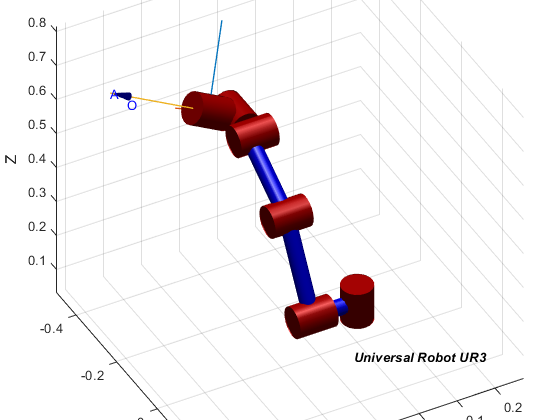


%Ploteamos los resultados
UR3.plot(qi,'workspace',[-0.4 0.4 -0.4 0.4 0 0.8], 'noa','view',[59.733 11.020])
hold on
UR3.plot(q,'workspace',[-0.4 0.4 -0.4 0.4 0 0.8], 'noa','view',[59.733 11.020])
xlim([-0.496 0.304])
ylim([-0.525 0.275])
zlim([0.031 0.816])
view([61.679 38.099])

%Observamos que aunque no es la configuración arbitraria planteada
%inicialmente se logra a la solución de la cinematica inversa, esto dando
%evidencia de la multiplicidad de soluciones que existen para la resolución
%del problema 
qi

qi =    -0.0273    0.5747    0.3884    0.1093   -0.1009         0


q

q =          0    0.5236    0.5236    0.5236    0.5236    0.5236


#### 4.Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores

#### 5.Compare los métodos

#### 6.Compruebe mediante su modelo geométrico inverso la configuración del robot para las posturas de la herramienta halladas en el anterior laboratorio, tales como puntos de calibración

syms Q1 Q2 Q3 Q4 Q5 Q6 real
MTH_0T1 = L(1).A(Q1);
MTH_1T2 = L(2).A(Q2);
MTH_2T3 = L(3).A(Q3);
MTH_3T4 = L(4).A(Q4);
MTH_4T5 = L(5).A(Q5);
MTH_5T6 = L(6).A(Q6);

% Con el tool MTH_0T6 = MTH_0T1 * MTH_1T2 * MTH_2T3 * MTH_3T4 * MTH_4T5 * MTH_5T6* R3.tool;
MTH_0T6 = MTH_0T1 * MTH_1T2 * MTH_2T3 * MTH_3T4 * MTH_4T5 * MTH_5T6;
MTH_0T6 = simplify(MTH_0T6);

d4=0.083;
d6=0.082;

%CalibPoint=[0,0.192,0.692];
CalibPoint=[0.01,0.2,0.3];


M0T6=transl(CalibPoint(1),CalibPoint(2),CalibPoint(3));
R=rotx(180,'deg');
PointMTH=[[R;[0 0 0]],[CalibPoint' ;1]]

PointMTH =     1.0000         0         0    0.0100
         0   -1.0000   -0.0000    0.2000
         0    0.0000   -1.0000    0.3000
         0         0         0    1.0000



Vec_0P5=PointMTH*[0;0;-d6;1];
Phi1=atan2(Vec_0P5(2),Vec_0P5(1));
Theta1_RHS=Phi1+acos(d4/(sqrt(Vec_0P5(1)^2 + Vec_0P5(2)^2)))

Theta1_RHS = 2.6643

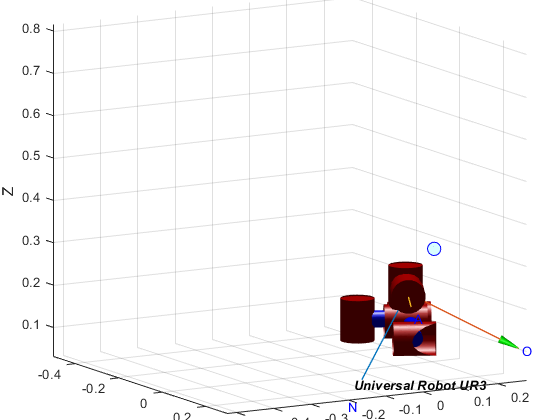

Theta1_LHS=Phi1-acos(d4/(sqrt(Vec_0P5(1)^2 + Vec_0P5(2)^2)));
Theta5_UW_LHS=angle(acos((CalibPoint(1)*sin(Theta1_LHS)-CalibPoint(2)*cos(Theta1_LHS)-d4)/d6));
Theta5_UW_RHS=angle(acos((CalibPoint(1)*sin(Theta1_RHS)-CalibPoint(2)*cos(Theta1_RHS)-d4)/d6));
Theta5_DW_LHS=angle(-acos((CalibPoint(1)*sin(Theta1_LHS)-CalibPoint(2)*cos(Theta1_LHS)-d4)/d6));
Theta5_DW_RHS=angle(-acos((CalibPoint(1)*sin(Theta1_RHS)-CalibPoint(2)*cos(Theta1_RHS)-d4)/d6));
MTH_6T0=PointMTH';

Theta6_UW_LHS=atan2((-MTH_6T0(1,2)*sin(Theta1_LHS)+MTH_6T0(2,2)*cos(Theta1_LHS))/(sin(Theta5_UW_LHS)),(MTH_6T0(1,1)*sin(Theta1_LHS)+MTH_6T0(2,1)*cos(Theta1_LHS))/(sin(Theta5_UW_LHS)));
Theta6_UW_RHS=atan2((-MTH_6T0(1,2)*sin(Theta1_RHS)+MTH_6T0(2,2)*cos(Theta1_RHS))/(sin(Theta5_UW_RHS)),(MTH_6T0(1,1)*sin(Theta1_RHS)+MTH_6T0(2,1)*cos(Theta1_RHS))/(sin(Theta5_UW_RHS)));
Theta6_DW_LHS=atan2((-MTH_6T0(1,2)*sin(Theta1_LHS)+MTH_6T0(2,2)*cos(Theta1_LHS))/(sin(Theta5_DW_LHS)),(MTH_6T0(1,1)*sin(Theta1_LHS)+MTH_6T0(2,1)*cos(Theta1_LHS))/(sin(Theta5_DW_LHS)));
Theta6_DW_RHS=atan2((-MTH_6T0(1,2)*sin(Theta1_RHS)+MTH_6T0(2,2)*cos(Theta1_RHS))/(sin(Theta5_DW_RHS)),(MTH_6T0(1,1)*sin(Theta1_RHS)+MTH_6T0(2,1)*cos(Theta1_RHS))/(sin(Theta5_DW_RHS)));
a2=0.244;
a3=0.213;

M0T1_RHS = L(1).A(Theta1_RHS);
M0T1_LHS = L(1).A(Theta1_LHS);

M4T6_UW_LHS = L(5).A(Theta5_UW_LHS)*L(6).A(Theta6_UW_LHS);
M4T6_UW_RHS = L(5).A(Theta5_UW_RHS)*L(6).A(Theta6_UW_RHS);
M4T6_DW_LHS = L(5).A(Theta5_DW_LHS)*L(6).A(Theta6_DW_LHS);
M4T6_DW_RHS = L(5).A(Theta5_DW_RHS)*L(6).A(Theta6_DW_RHS);

P4_UW_LHS=inv(M0T1_LHS)*PointMTH*inv(M4T6_UW_LHS);
P4_UW_RHS=inv(M0T1_RHS)*PointMTH*inv(M4T6_UW_RHS);
P4_DW_LHS=inv(M0T1_LHS)*PointMTH*inv(M4T6_DW_LHS);
P4_DW_RHS=inv(M0T1_RHS)*PointMTH*inv(M4T6_DW_RHS);


P4xz_UW_LHS=sqrt(P4_UW_LHS(1,4)^2 + P4_UW_LHS(3,4)^2);
P4xz_UW_RHS=sqrt(P4_UW_RHS(1,4)^2 + P4_UW_RHS(3,4)^2);
P4xz_DW_LHS=sqrt(P4_UW_LHS(1,4)^2 + P4_DW_LHS(3,4)^2);
P4xz_DW_RHS=sqrt(P4_UW_RHS(1,4)^2 + P4_DW_RHS(3,4)^2);

Phi3_UW_LHS=(-abs(P4xz_UW_LHS)^2 + a2^2 +a3^2)/(2*a2*a3);
Phi3_UW_RHS=(-abs(P4xz_UW_RHS)^2 + a2^2 +a3^2)/(2*a2*a3);
Phi3_DW_LHS=(-abs(P4xz_DW_LHS)^2 + a2^2 +a3^2)/(2*a2*a3);
Phi3_DW_RHS=(-abs(P4xz_DW_RHS)^2 + a2^2 +a3^2)/(2*a2*a3);

%Codo arriba del plano xz
Theta3_UW_LHS_UP=angle(acos((abs(P4xz_UW_LHS)^2 - a2^2 -a3^2)/(2*a2*a3)));
Theta3_UW_RHS_UP=angle(acos((abs(P4xz_UW_RHS)^2 - a2^2 -a3^2)/(2*a2*a3)));
Theta3_DW_LHS_UP=angle(acos((abs(P4xz_DW_LHS)^2 - a2^2 -a3^2)/(2*a2*a3)));
Theta3_DW_RHS_UP=angle(acos((abs(P4xz_DW_RHS)^2 - a2^2 -a3^2)/(2*a2*a3)));
%Codo abajo del plano
Theta3_UW_LHS_DOWN=angle(-acos((abs(P4xz_UW_LHS)^2 - a2^2 -a3^2)/(2*a2*a3)));
Theta3_UW_RHS_DOWN=angle(-acos((abs(P4xz_UW_RHS)^2 - a2^2 -a3^2)/(2*a2*a3)));
Theta3_DW_LHS_DOWN=angle(-acos((abs(P4xz_DW_LHS)^2 - a2^2 -a3^2)/(2*a2*a3)));
Theta3_DW_RHS_DOWN=angle(-acos((abs(P4xz_DW_RHS)^2 - a2^2 -a3^2)/(2*a2*a3)));


Theta2_UW_LHS_UP=(atan2(-P4_UW_LHS(3,4),-P4_UW_LHS(1,4)))-angle(asin((-a3*sin(Phi3_UW_LHS))/abs(P4xz_UW_LHS)));
Theta2_UW_RHS_UP=(atan2(-P4_UW_RHS(3,4),-P4_UW_RHS(1,4)))-angle(asin((-a3*sin(Phi3_UW_RHS))/abs(P4xz_UW_RHS)));
Theta2_DW_LHS_UP=(atan2(-P4_DW_LHS(3,4),-P4_DW_LHS(1,4)))-angle(asin((-a3*sin(Phi3_DW_LHS))/abs(P4xz_DW_LHS)));
Theta2_DW_RHS_UP=(atan2(-P4_DW_RHS(3,4),-P4_DW_RHS(1,4)))-angle(asin((-a3*sin(Phi3_DW_RHS))/abs(P4xz_DW_RHS)));

MTH_0T3_UW_LHS_UP = L(1).A(Theta1_LHS)*L(2).A(Theta2_UW_LHS_UP)*L(3).A(Theta3_UW_LHS_UP);
MTH_0T3_UW_RHS_UP = L(1).A(Theta1_RHS)*L(2).A(Theta2_UW_RHS_UP)*L(3).A(Theta3_UW_RHS_UP);
MTH_0T3_DW_LHS_UP = L(1).A(Theta1_LHS)*L(2).A(Theta2_DW_LHS_UP)*L(3).A(Theta3_DW_LHS_UP);
MTH_0T3_DW_RHS_UP = L(1).A(Theta1_RHS)*L(2).A(Theta2_DW_RHS_UP)*L(3).A(Theta3_DW_RHS_UP);

M3T4_UW_LHS_UP=inv(MTH_0T3_UW_LHS_UP)*PointMTH*inv(M4T6_UW_LHS);
M3T4_UW_RHS_UP=inv(MTH_0T3_UW_RHS_UP)*PointMTH*inv(M4T6_UW_RHS);
M3T4_DW_LHS_UP=inv(MTH_0T3_DW_LHS_UP)*PointMTH*inv(M4T6_DW_LHS);
M3T4_DW_RHS_UP=inv(MTH_0T3_DW_RHS_UP)*PointMTH*inv(M4T6_DW_RHS);

Theta4_UW_LHS_UP=atan2(M3T4_UW_LHS_UP(2,1),M3T4_UW_LHS_UP(1,1));
Theta4_UW_RHS_UP=atan2(M3T4_UW_RHS_UP(2,1),M3T4_UW_RHS_UP(1,1));
Theta4_DW_LHS_UP=atan2(M3T4_DW_LHS_UP(2,1),M3T4_DW_LHS_UP(1,1));
Theta4_DW_RHS_UP=atan2(M3T4_DW_RHS_UP(2,1),M3T4_DW_RHS_UP(1,1));


UW_LHS_UP=[Theta1_LHS Theta2_UW_LHS_UP Theta3_UW_LHS_UP Theta4_UW_LHS_UP Theta5_UW_LHS Theta6_UW_LHS];
UW_RHS_UP=[Theta1_RHS Theta2_UW_RHS_UP Theta3_UW_RHS_UP Theta4_UW_RHS_UP Theta5_UW_RHS Theta6_UW_RHS];
DW_LHS_UP=[Theta1_LHS Theta2_DW_LHS_UP Theta3_DW_LHS_UP Theta4_DW_LHS_UP Theta5_DW_LHS Theta6_DW_LHS];
DW_RHS_UP=[Theta1_RHS Theta2_DW_RHS_UP Theta3_DW_RHS_UP Theta4_DW_RHS_UP Theta5_DW_RHS Theta6_DW_RHS];




Theta2_UW_LHS_DOWN=(atan2(-P4_UW_LHS(3,4),-P4_UW_LHS(1,4)))-angle(asin((-a3*sin(Phi3_UW_LHS))/abs(P4xz_UW_LHS)));
Theta2_UW_RHS_DOWN=(atan2(-P4_UW_RHS(3,4),-P4_UW_RHS(1,4)))-angle(asin((-a3*sin(Phi3_UW_RHS))/abs(P4xz_UW_RHS)));
Theta2_DW_LHS_DOWN=(atan2(-P4_DW_LHS(3,4),-P4_DW_LHS(1,4)))-angle(asin((-a3*sin(Phi3_DW_LHS))/abs(P4xz_DW_LHS)));
Theta2_DW_RHS_DOWN=(atan2(-P4_DW_RHS(3,4),-P4_DW_RHS(1,4)))-angle(asin((-a3*sin(Phi3_DW_RHS))/abs(P4xz_DW_RHS)));

MTH_0T3_UW_LHS_DOWN = L(1).A(Theta1_LHS)*L(2).A(Theta2_UW_LHS_DOWN)*L(3).A(Theta3_UW_LHS_DOWN);
MTH_0T3_UW_RHS_DOWN = L(1).A(Theta1_RHS)*L(2).A(Theta2_UW_RHS_DOWN)*L(3).A(Theta3_UW_RHS_DOWN);
MTH_0T3_DW_LHS_DOWN = L(1).A(Theta1_LHS)*L(2).A(Theta2_DW_LHS_DOWN)*L(3).A(Theta3_DW_LHS_DOWN);
MTH_0T3_DW_RHS_DOWN = L(1).A(Theta1_RHS)*L(2).A(Theta2_DW_RHS_DOWN)*L(3).A(Theta3_DW_RHS_DOWN);

M3T4_UW_LHS_DOWN=inv(MTH_0T3_UW_LHS_DOWN)*PointMTH*inv(M4T6_UW_LHS);
M3T4_UW_RHS_DOWN=inv(MTH_0T3_UW_RHS_DOWN)*PointMTH*inv(M4T6_UW_RHS);
M3T4_DW_LHS_DOWN=inv(MTH_0T3_DW_LHS_DOWN)*PointMTH*inv(M4T6_DW_LHS);
M3T4_DW_RHS_DOWN=inv(MTH_0T3_DW_RHS_DOWN)*PointMTH*inv(M4T6_DW_RHS);

Theta4_UW_LHS_DOWN=atan2(M3T4_UW_LHS_DOWN(2,1),M3T4_UW_LHS_DOWN(1,1));
Theta4_UW_RHS_DOWN=atan2(M3T4_UW_RHS_DOWN(2,1),M3T4_UW_RHS_DOWN(1,1));
Theta4_DW_LHS_DOWN=atan2(M3T4_DW_LHS_DOWN(2,1),M3T4_DW_LHS_DOWN(1,1));
Theta4_DW_RHS_DOWN=atan2(M3T4_DW_RHS_DOWN(2,1),M3T4_DW_RHS_DOWN(1,1));


UW_LHS_DOWN=[Theta1_LHS Theta2_UW_LHS_DOWN Theta3_UW_LHS_DOWN Theta4_UW_LHS_DOWN Theta5_UW_LHS Theta6_UW_LHS];
UW_RHS_DOWN=[Theta1_RHS Theta2_UW_RHS_DOWN Theta3_UW_RHS_DOWN Theta4_UW_RHS_DOWN Theta5_UW_RHS Theta6_UW_RHS];
DW_LHS_DOWN=[Theta1_LHS Theta2_DW_LHS_DOWN Theta3_DW_LHS_DOWN Theta4_DW_LHS_DOWN Theta5_DW_LHS Theta6_DW_LHS];
DW_RHS_DOWN=[Theta1_RHS Theta2_DW_RHS_DOWN Theta3_DW_RHS_DOWN Theta4_DW_RHS_DOWN Theta5_DW_RHS Theta6_DW_RHS];

hold on
plot3(CalibPoint(1),CalibPoint(2),CalibPoint(3),'-o','Color','b','MarkerSize',10,'MarkerFaceColor','#D9FFFF')
UR3.plot(DW_RHS_DOWN,'workspace',[-0.4 0.4 -0.4 0.4 0 0.8], 'noa','view',[59.733 11.020])

#### 7.Proponga 4 posturas (x, y, z, roll, pitch, yaw) que estén dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla 1.

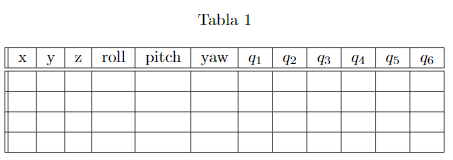

#### 8.Haciendo  uso  de  la  GUI  verifique  que  con  la  configuración  calculada  se  obtiene  la  postura  indicada  de  la herramienta.  Haga  capturas  de  pantalla  resaltando  con  cotas  los  valores $x \;  y \; z$,  e  incluya  en  el  informe  los resultados

#### 9.Actualice la GUI para que tenga la opción de ingresar la posición de la herramienta, obtener la configuración del robot mediante cinemática inversa y observar el robot en la posición. Compruebe su funcionamiento